# RCS of Satellite

Create satellite surface from an STL file.

Input model dimensions

% Promput user for model type
model_type = input("Enter model type ('Rectangular','Cylinder','Sphere', or 'STL'): ");

% Additional settings
if strcmp(model_type,'STL')
    % Request name of STL file
    filename = input("Enter name of STL file (located in the 'Satellites' directory): ");
    
    % Load the file
    filename = join(['Satellites/',filename]);
    p = platform;
    p.FileName = [filename]; 
    p.Units = 'm';
    
    % Set mesh length based on maximum feature size
    maxsize = p.getMaxFeatureSize();
    if maxsize < 1
        MaxEdgeLength = 0.1;
    else
        MaxEdgeLength = 0.5;
    end
    
elseif strcmp(model_type,'Rectangular')
    % Rectangular Prism
    
    % Request dimensions
    W = input("Enter width (x-coord) of rectangular prism (in meters): ")
    D = input("Enter depth (y-coord) of rectangular prism (in meters): ")
    H = input("Enter height (z-coord) of rectangular prism (in meters): ")
    
    % Create triangulation
    % Based on geometry of airbusA.STL (2 x 2 x 2m cube)
    tri = stlread('Satellites/airbusA.STL');
    P = tri.Points;
    P = P*0.5; % Normalize to 1x1x1m cube
    T = tri.ConnectivityList;
    
    % Scale dimensions
    P(:,1) = W*P(:,1); % Width
    P(:,2) = D*P(:,2); % Depth
    P(:,3) = H*P(:,3); % Height  
    
    % Create triangulation object
    TR = triangulation(T,P);
    % Save to temporary STL file
    filename = join(['Satellites/','temp_geometry.STL']);
    stlwrite(TR,filename); % Wrtite to file
    
    % Load the file
    p = platform;
    p.FileName = [filename]; 
    p.Units = 'm';
    
    % Set mesh length based on minimum feature size
    minsize = min([W,D,H]);
    if minsize < 1
        MaxEdgeLength = 0.5*minsize;
    else
        MaxEdgeLength = 0.5;
    end
    
    % Delete temporary file
    %delete 'Satellites/temp_geometry.STL';
    
elseif strcmp(model_type,'Cylinder')
    % Cylinder
    
    % Request dimensions and orientation
    R = input("Enter radius of cylinder (in meters): ")
    L = input("Enter length of cylinder (in meters): ")
    orient = input("Enter orientation of cylinder ('H' = horizontal, 'V' = vertical): ")
    
    % Create triangulation
    % Based on geometry of airbusB.STL (Cylinder with R=1m, L=2.5m)
    tri = stlread('Satellites/airbusB.STL');
    P1 = tri.Points;
    P1(:,2) = P1(:,2)/2.5; % Normalize length to 1m
    T = tri.ConnectivityList;
    
    % Scale points
    P1(:,2) = L*P1(:,2);
    
    % Change orientation
    if strcmp(orient,'V')
        % Vertical. Switch 2,3 columns
        P = P1(:,[1 3 2]);
    else
        P = P1
    end
    
    % Create triangulation object
    TR = triangulation(T,P);
    % Save to temporary STL file
    filename = join(['Satellites/','temp_geometry.STL']);
    stlwrite(TR,filename); % Wrtite to file
    
    % Load the file
    p = platform;
    p.FileName = [filename]; 
    p.Units = 'm';
    
    % Set mesh length based on minimum feature size
    minsize = min([2*R,L]);
    if minsize < 1
        MaxEdgeLength = 0.5*minsize;
    else
        MaxEdgeLength = 0.5;
    end
    
    % Delete temporary file
    %delete 'Satellites/temp_geometry.STL';

elseif strcmp(model_type,'Sphere')
    % Sphere
    
    % Request dimensions
    R = input("Enter radius of sphere (in meters): ")
    
    [x,y,z] = sphere(20);
    x = x*R; y = y*R; z = z*R; % Scale
    fvc = surf2patch(x,y,z,'triangles');
    P = fvc.vertices;
    T = fvc.faces;
    
    % Create triangulation object
    TR = triangulation(T,P);
    % Save to temporary STL file
    filename = join(['Satellites/','temp_geometry.STL']);
    stlwrite(TR,filename); % Wrtite to file
    
    % Load the file
    p = platform;
    p.FileName = [filename]; 
    p.Units = 'm';
    
    % Set mesh length based on radius
    minsize = R;
    MaxEdgeLength = 0.3*minsize;
    
    % Delete temporary file
    %delete 'Satellites/temp_geometry.STL';
    
    

else
    % Error
    
   
end

R = 1.4000

L = 2.1000

orient = 'H'

P =     1.0592    2.1000    1.9982
    1.0000    2.1000    2.0000
    1.0000         0    2.0000
    0.9408         0    1.9982
    0.9408    2.1000    1.9982
    0.8231    2.1000    1.9842
    0.8231         0    1.9842
    0.7079    2.1000    1.9564
    0.7079         0    1.9564
    0.5969    2.1000    1.9151


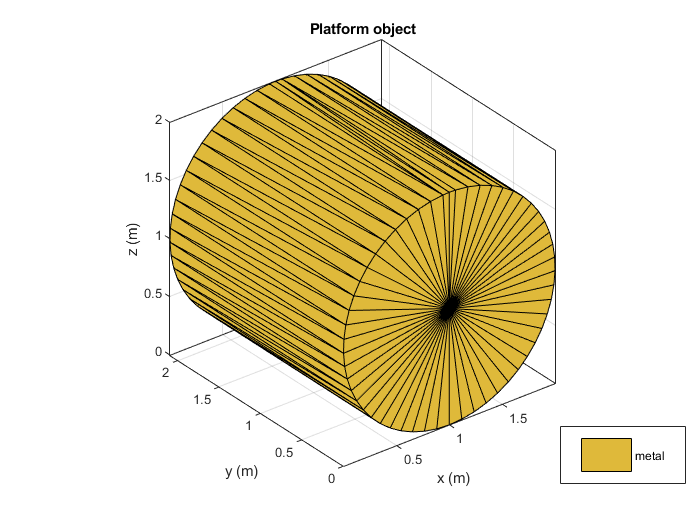

%p = platform;
%p.FileName = ['Satellites/GRACE-FO.STL']; 
p.Units = 'm';
freq = 450e6;
figure
show(p)

Mesh the platform with edge length of 0.5

Determine dimensions from average radius.

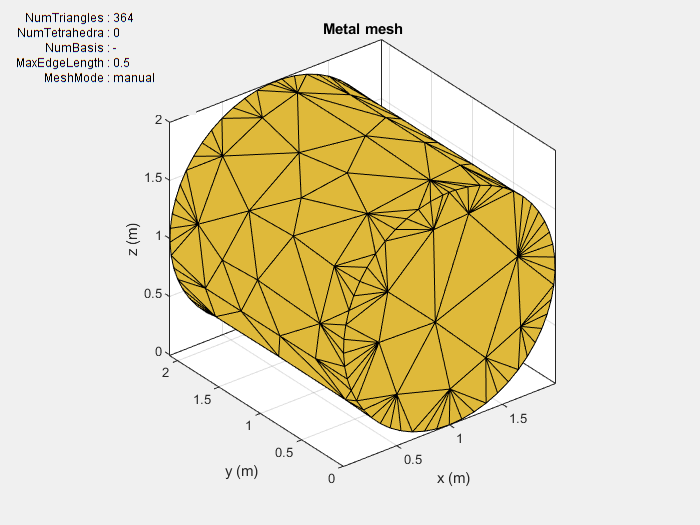

figure
mesh(p,'MaxEdgeLength', MaxEdgeLength)
axis equal

Sweep over the elevation with a vertically polarized E-field. Plot the RCS at 450 MHz in the azimuth plane.

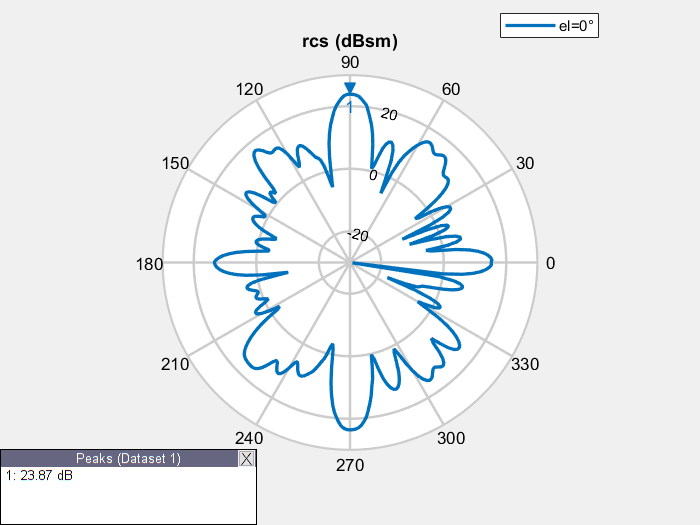

az = 0:1:360;
el = 0;
figure 
rcs(p,freq,az,el)

[rcsval,az,el] = rcs(p,freq,az,el)

rcsval =    15.1737
   15.4189
   15.0391
   14.2438
   12.9904
   11.1408
    8.4184
    4.1735
   -3.5717
   -5.3628


az =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


el = 0

pow = db2pow(rcsval);
pow_avg = mean(pow);
RCSavg = mean(rcsval)

RCSavg = 7.8233

RCSavgp = pow2db(pow_avg)

RCSavgp = 13.5573

*Copyright 2019 The MathWorks, Inc.*